# Homework 10 (Solution)

Math 3607

Tae Eun Kim

Several problems in this homework set involves lengthy by-hand calculations. These solutions are written in a separate document. This mlx file contains solutions for computer exercises. 

## Problem 1 (Higher-Order Forward Difference)

See the attached document. 

## Problem 2 (LM 14.1--12)

### (a) Extrapolation for 4th-order centerend difference

The fourth-order centered difference formula is given by

$\displaystyle D_h^{\rm [4c]} \{f\} (x) = \frac{f(x-2h) - 8f(x-h) + 8(x+h) - f(x+2h)}{12h}$.

See the attached document for derivation. We modify the textbook script `diff1` by implementing this formula as below:

%% script m-file: diff1 (modified)
f = @(x) sin(x.^2);
fdrv = @(x) 2*x.*cos(x.^2);
Df = @(x,h) (f(x+h) - f(x))./h;          % 1st-order FD
Dfc = @(x,h) (f(x+h) - f(x-h))./(2*h);   % 2nd-order CD
Df4c = @(x,h) ...                        % 4th-order CD
    (f(x-2*h) - 8*f(x-h) + 8*f(x+h) - f(x+2*h))./(12*h);
x = 1/3;
h0 = 0.1;
nr_h = 35;
h = h0*2.^(-[0:nr_h]');
A(:,1) = h;
A(:,2) = Df(x,h) - fdrv(x);
A(:,3) = Dfc(x,h) - fdrv(x);
A(:,4) = Df4c(x,h) - fdrv(x);
disp('      h         errors')

      h         errors


disp(A)

                       0.1        0.0953800307503522       -0.0012624336679421      0.000129128211100116
                      0.05        0.0481156495713236      -0.00030952874788992      8.10622546054685e-06
                     0.025        0.0241485170712513     -7.70018004009332e-05      5.07182095432768e-07
                    0.0125        0.0120951469886871      -1.9226669620287e-05      3.17073064470819e-08
                   0.00625       0.00605258336365655     -4.80518102807803e-06      1.98183547350794e-09
                  0.003125       0.00302751828247738      -1.2012023592467e-06      1.23864696277565e-10
                 0.0015625          0.00151406259914     -3.00294775157361e-07      7.75568498312396e-12
                0.00078125       0.00075710676755103     -7.50733292198547e-08      4.85944617878431e-13
               0.000390625      0.000378572201298888     -1.87683507624214e-08     -2.76445533131664e-14
              0.0001953125      0.000189290798871533   

Confirm the accuracy on the log-log graph below.

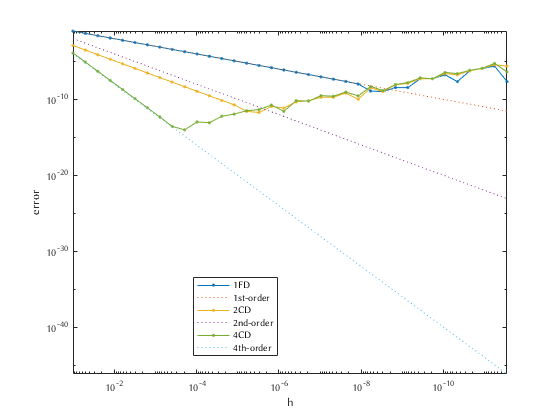

clf
% 1FD
loglog(A(:,1), abs(A(:,2)), '.-'), hold on
loglog(A(:,1), A(:,1), ':')
% 2CD
loglog(A(:,1), abs(A(:,3)), '.-')
loglog(A(:,1), A(:,1).^2, ':')
% 4CD
loglog(A(:,1), abs(A(:,4)), '.-')
loglog(A(:,1), A(:,1).^4, ':')
% Prettifying
xlabel('h'),ylabel('error')
axis tight
legend('1FD', '1st-order', '2CD', '2nd-order', '4CD', '4th-order', 'Location', 'best')
set(gca, 'xdir', 'Reverse')

**Question.** Can you confirm from the previous graph the optimal $h$ for each method?

### (b) Second Derivatives

clear A

The second-order centered difference method for $f''(x)$ is given by

$\displaystyle f''(x) \approx \frac{ f(x+h) - 2f(x) + f(x-h) }{h^2}$.

By Richardson extrapolation, we obtained the fourth-order centered difference formula for $f''(x)$

$\displaystyle f''(x) \approx \frac{ -f(x-2h)+16f(x-h) -6f(x) + 16f(x+h) - f(x+2h)}{12h^2}$.

%% script m-file: diff1 (modified)
f = @(x) sin(x.^2);
f2drv = @(x) 2*cos(x.^2) - 4*x.^2.*sin(x.^2);
D2fc = @(x,h) (f(x+h) - 2*f(x) + f(x-h))./(h.^2);   % 2nd-order CD
D2f4c = @(x,h) ...                                  % 4th-order CD
    (-f(x-2*h) + 16*f(x-h) - 30*f(x) + 16*f(x+h) - f(x+2*h))./(12*h.^2);
x = 1/3;
h0 = 0.1;
nr_h = 20;
h = h0*2.^(-[0:nr_h]');
A(:,1) = h;
A(:,2) = D2fc(x,h) - f2drv(x);
A(:,3) = D2f4c(x,h) - f2drv(x);
disp('      h         errors')

      h         errors


disp(A)

                       0.1      -0.00553656048525486      0.000114478122608119
                      0.05      -0.00137871608259621       7.2320516149027e-06
                     0.025      -0.00034433911895837      4.53202243289041e-07
                    0.0125     -8.60635219601669e-05      2.83435579451208e-08
                   0.00625     -2.15145520576776e-05      1.77094716669046e-09
                  0.003125     -5.37855569637813e-06      1.07981179553462e-10
                 0.0015625     -1.34463973955334e-06     -8.66640093022397e-12
                0.00078125     -3.36197698569407e-07     -8.82471873353552e-11
               0.000390625     -8.42449288107616e-08      -4.0467540429745e-10
              0.0001953125     -2.13988449182523e-08     -1.02616359853869e-09
              9.765625e-05     -6.48313180917626e-09     -3.08768477452759e-09
             4.8828125e-05     -6.48313180917626e-09     -1.18188339115477e-08
            2.44140625e-05     -6.48313180917626e-09

Plot the errors on the log-log graph to confirm the order of accuracy:

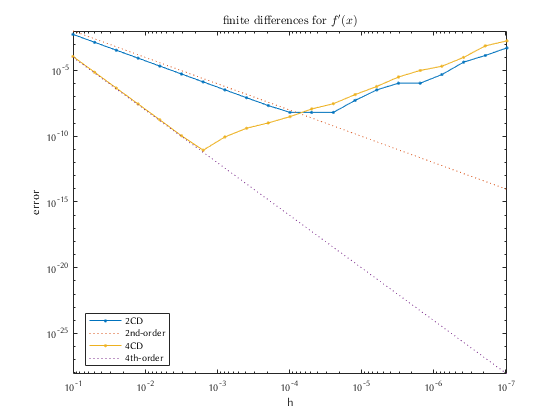

clf
loglog(A(:,1), abs(A(:,2)), '.-'),hold on
loglog(A(:,1), A(:,1).^2, ':')

loglog(A(:,1), abs(A(:,3)), '.-')
loglog(A(:,1), A(:,1).^4, ':')
xlabel('h'),ylabel('error')
title('finite differences for $f''(x)$', 'Interpreter', 'latex')
axis tight
legend('2CD', '2nd-order', '4CD', '4th-order', 'Location', 'best')
set(gca, 'xdir', 'Reverse')

## Problem 3 (LM 14.1--17, Sequences Converging to $\pi$)

Begin by defining anonymous functions

p = @(n) n.*sin(pi./n);      % 2nd-order; underestimate
P = @(n) n.*tan(pi./n);      % 2nd-order; overestimate
B = @(n) (p(n) + P(n))/2;    % 2nd-order; better than p(n) and P(n)
R = @(n) (2*p(n) + P(n))/3;  % 4th-order; obtained from extrapolation

The question asks that we calculate the sequences for $n=48$ and $n=96$; I will do some more. Below is a quick and dirty way to calculate them.

n = 48*2.^(0:9)';
calc = [p(n), P(n), B(n), R(n)];
disp([n, calc])

                        48          3.13935020304687          3.14608621513143          3.14271820908915          3.14159554040839
                        96          3.14103195089051          3.14271459964537          3.14187327526794           3.1415928338088
                       192          3.14145247228546          3.14187304997982          3.14166276113264          3.14159266485025
                       384          3.14155760791186          3.14166274705685          3.14161017748435          3.14159265429352
                       768          3.14158389214832          3.14161017660469           3.1415970343765          3.14159265363377
                      1536          3.14159046322805          3.14159703432153          3.14159374877479          3.14159265359254
                      3072          3.14159210599927          3.14159374877135          3.14159292738531          3.14159265358996
                      6144          3.14159251669216           3.1415929273851     

The errors:

disp([n, calc-pi])

                        48      -0.00224245054292638       0.00449356154164171       0.00112555549935767      2.88681859617057e-06
                        96     -0.000560702699283766       0.00112194605557514      0.000280621678145465      1.80219002388071e-07
                       192     -0.000140181304331577      0.000280396390030191       7.0107542849307e-05      1.12604556790075e-08
                       384     -3.50456779356634e-05      7.00934670549991e-05      1.75238945594458e-05      7.03728186834951e-10
                       768     -8.76144147543556e-06      1.75230148959926e-05      4.38078671027853e-06      4.39812630759207e-11
                      1536     -2.19036174353704e-06      4.38073173247844e-06      1.09518499424865e-06      2.74846811976204e-12
                      3072     -5.47590521815522e-07      1.09518155877453e-06      2.73795518701547e-07      1.71862524211974e-13
                      6144     -1.36897636338063e-07       2.7379530376237e-07     

If you want to have a finer control over how the numbers are formatted, use `fprintf` as demonstrated many times in other homework solutions or in class. 

## Problem 4 (LM 14.2--3(b), Spiral)

Simply modify the integrands in the Euler spiral code provided for Lecture 31 and 32. 

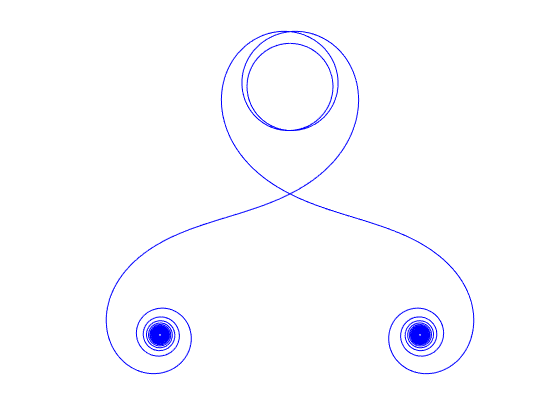

T = 15;
h = 0.001;
t = (0:h:T);
tmid = ( t(1:end-1)+t(2:end) )/2;
fx = @(z) cos(0.25*z.^3-5.2*z);
fy = @(z) sin(0.25*z.^3-5.2*z);
Ix = h/6 * ( fx(t(1:end-1)) + 4*fx(tmid) + fx(t(2:end)) );
Iy = h/6 * ( fy(t(1:end-1)) + 4*fy(tmid) + fy(t(2:end)) );
x = cumsum(Ix);
y = cumsum(Iy);

clf
plot(x, y, 'b', -x, y, 'b')
axis equal, axis off
grid on

## Problem 5 (LM 14.2--6, Smoothness and Accuracy)

## Problem 6 (LM 14.2--11(a), Extrapolation for Composite Methods)

See the attached document.